# Control System Dynamics

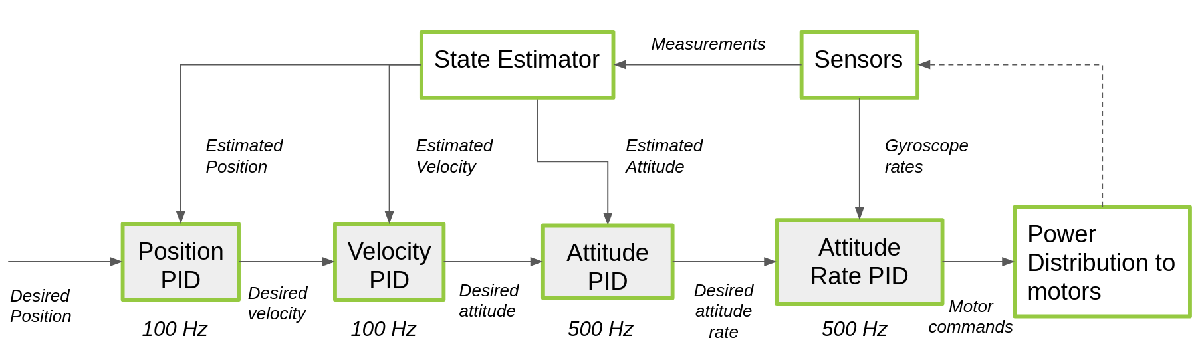

syms J % constants
syms X Y Z L M N % inputs
F_app = [X; Y; Z];
M_app = [L; M; N];

p_E_dot = V_E; % problem 8
% Theta_dot = Theta_dot; % problem 6 
V_b_dot = 1/m * (F_app + F_gb ... % problem 7
                 + F_Ab       ... % problem 9
                 - cross(omega_bE, m*V_b)); % omega_bE from problem 6
omega_bE_dot = J^(-1) * (M_app - cross(omega_bE, J*omega_bE)); % J is moment of inertia for the drone (not incl. propellors)

f = [p_E_dot; Theta_dot; V_b_dot; omega_bE_dot];

x = [p_E; Theta; V_b; omega_bE];
u = [F_app; M_app];

x_0 = zeros(12, 1);
u_0 = [0; 0; -m*g; 0; 0; 0];

## Problem 11

f_x = jacobian(f, x);
A = subs(f_x, x, x_0)

f_u = jacobian(f, u);
B = subs(f_u, u, u_0)
